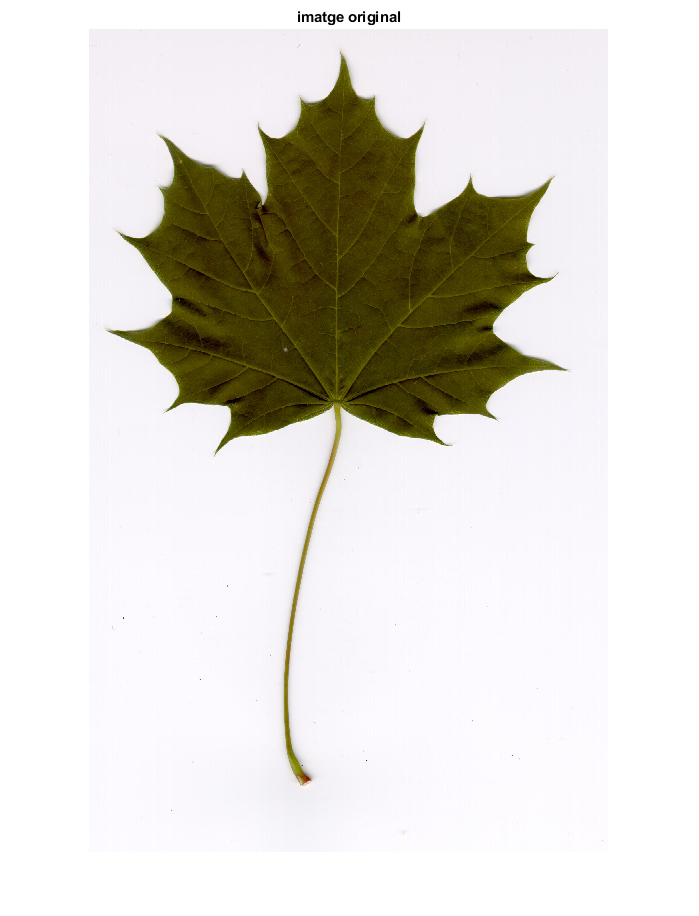

im=imread('l2nr001.jpg');
%im=imresize(im,1/4);
imshow(im), title('imatge original')

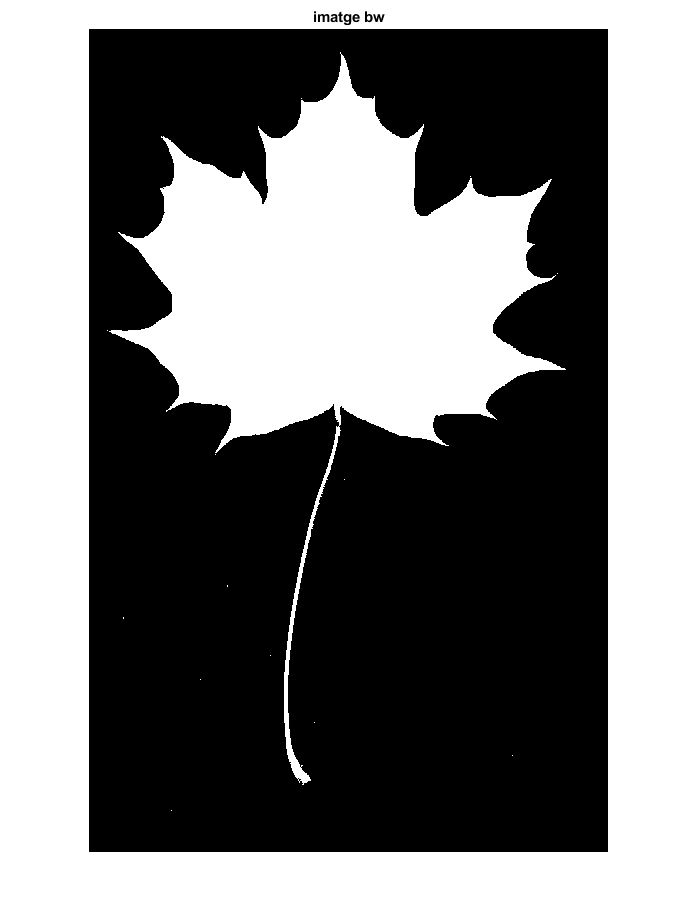

bw = im2bw(im,0.6);
bw = ~bw;
imshow(bw), title('imatge bw')

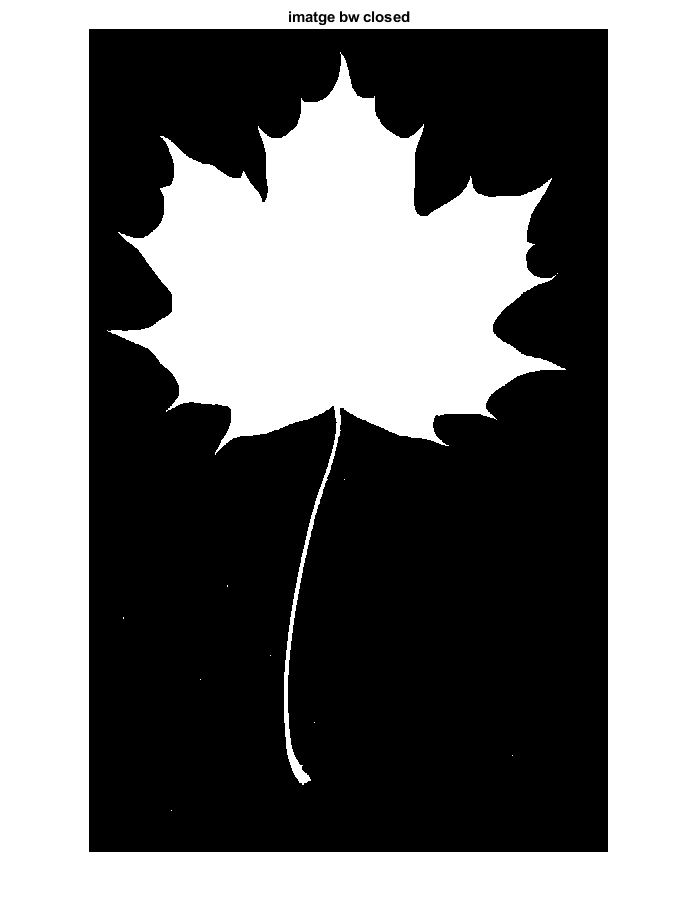

ee = strel('disk',5);
bw = imclose(bw,ee);
imshow(bw), title('imatge bw closed')

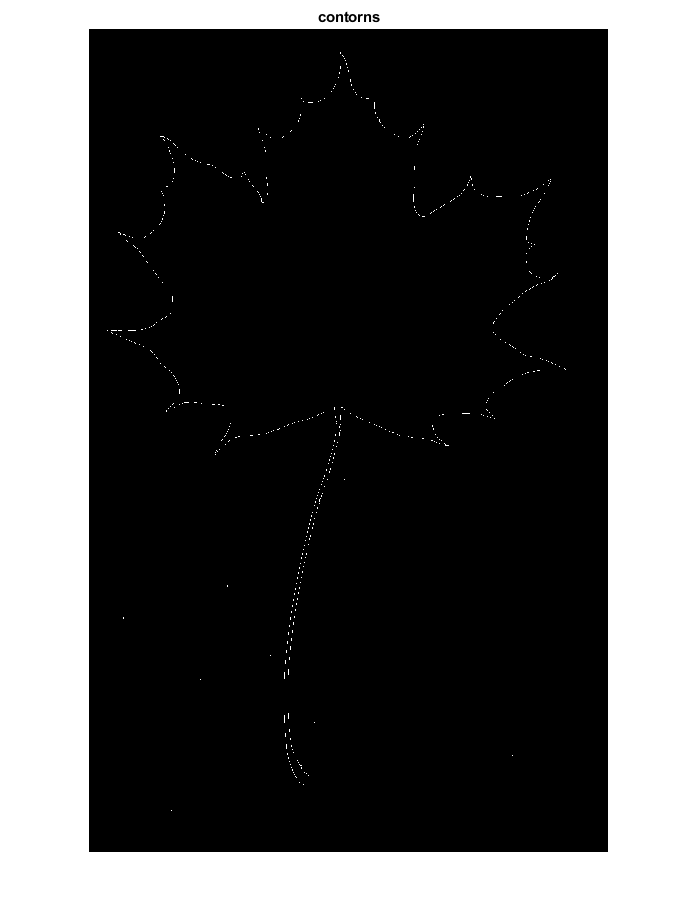


ero=imerode(bw,strel('disk',1));
cont=xor(ero,bw);
figure,imshow(cont), title('contorns')

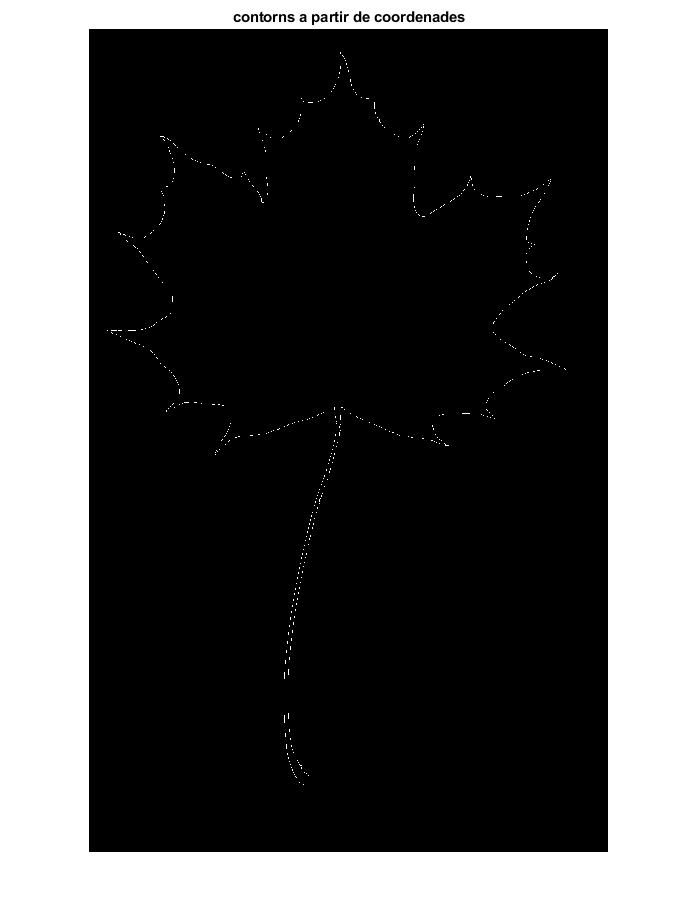


% obtenim les coordenades del contorn
[fila col] = find(bw,1); % Busquem el primer píxel
B = bwtraceboundary(bw,[fila col],'E'); %direccio est a l'atzar
% B conté les coordenades
% Ho comprovem mostrant el resultat
aux=zeros(size(bw));
aux(sub2ind(size(aux),B(:,1),B(:,2)))=1;
figure,imshow(aux),title ('contorns a partir de coordenades')

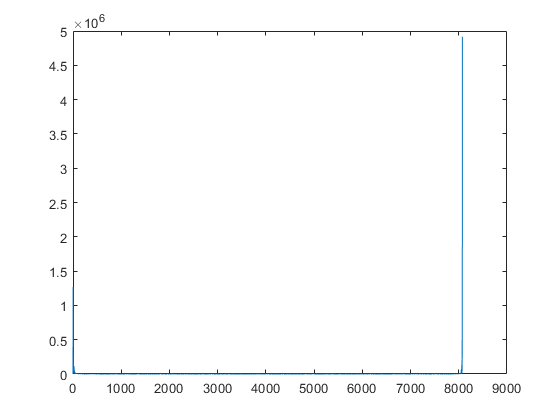


% centrem coordenades
mig=mean(B);
B(:,1)=B(:,1)-mig(1);
B(:,2)=B(:,2)-mig(2);
% Convertim les coordenades a complexes
s= B(:,1) + i*B(:,2);
% Cal que la dimensio del vector sigui parell
[mida bobo]=size(B);
if(mida/2~=round(mida/2))
 s(end+1,:)=s(end,:); %dupliquem l'ultim
 mida=mida+1;
end
% Calculem la Fast Fourier Transform
z=fft(s);
% representem l’espectre
figure,plot(abs(z))

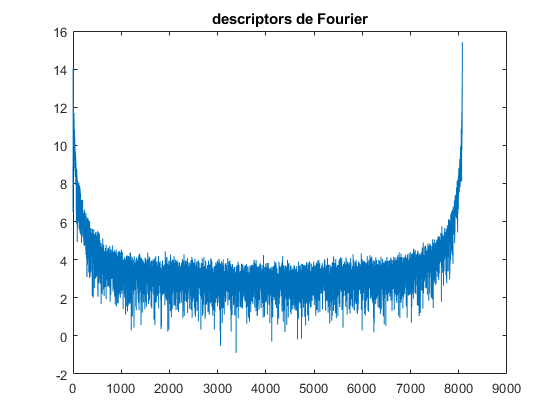

% ho displaiem logaritmic perque no es veu res
figure,plot(log(abs(z))), title ('descriptors de Fourier')

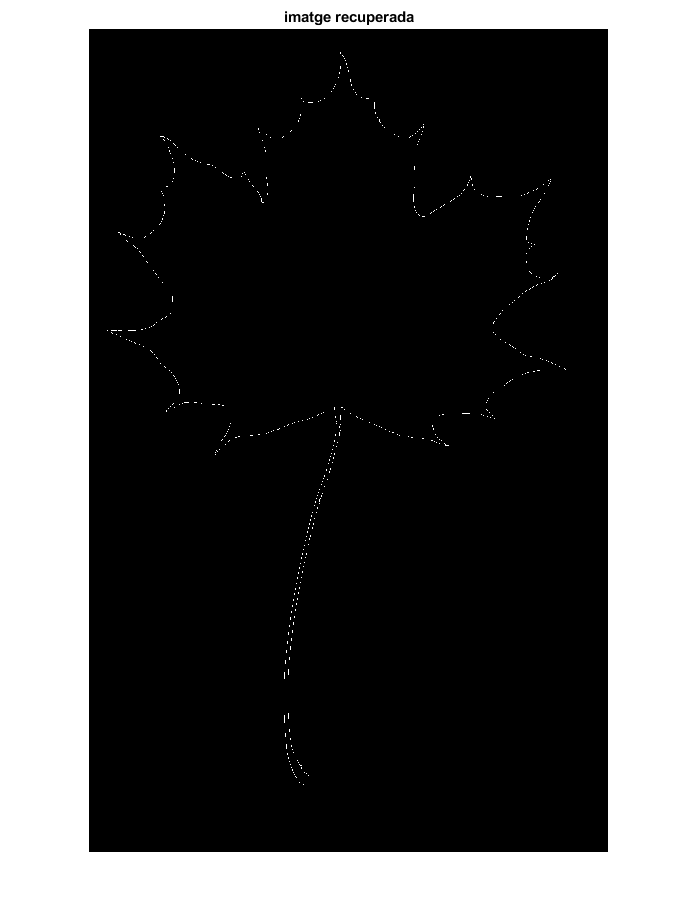


% Recuperem la imatge original per comprovar que el procés és reversible
ss=ifft(z); % Transformada de Fourier inversa
files= round(real(ss)+mig(1));
cols=round(imag(ss)+mig(2));
aux(:,:)=0;
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux), title('imatge recuperada')


% %% Reduim la quantitat de descriptors de Fourier
% N=60; % agafem N descriptors
% tmp=z;
% tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
% figure, plot(log(abs(tmp))), title ('Només 30 descriptors')
% % Tornem al pla imatge a partir de l’espectre modificat
% ss2=ifft(tmp);
% % Les coordenades resultants poden sortir del rang de la imatge original
% % Creo una imatge més gran per a que les coordenades no s'em surtin de mare
% mida=800;
% files= round(real(ss2)+mida/2);
% cols=round(imag(ss2)+mida/2);
% aux=logical(zeros(mida));
% aux(sub2ind(size(aux),files,cols))=1;
% figure,imshow(aux)
% title(['Numero de descriptors: ',num2str(N)]);

